SporesImagesPath=fullfile('D:\Spores\Images\X40');
Images=imageDatastore(SporesImagesPath,'FileExtensions','.tif');

varType={'string','single'};
varName={'FileName','numDetectedSpores'};
CountedSpores=table('Size',[numel(Images.Files) 2],'VariableTypes',varType,'VariableName',varName);
for i=1:numel(Images.Files)
    warning('off','all');
    [I,info]=readimage(Images,i);
   
    I=rgb2gray(I);
    figure;
    imshow(I);
    [Centers,Radii]=imfindcircles(I,[5 16],'Sensitivity',0.8,'EdgeThreshold',0.05,'ObjectPolarity','dark');
    viscircles(Centers,Radii);
    nSpores=numel(Radii); 
    [x y]=meshgrid(1:size(I,2),1:size(I,1));
%     SporesArea=0;
%     for j=1:numel(Radii)
%          Circle=(x-Centers(j,1)).^2+(y-Centers(j,2)).^2<Radii(j).^2;
%          SporesArea=SporesArea + numel(Circle);
%     end
    CountedSpores(i,:)={sprintf('%s',info.Filename(22:end)),nSpores};    
end
CountedSpores

%%METHOD1=does not work well->salt&pepper pattern (Image 3)
I=readimage(Images,2);
I=rgb2gray(I);
se=strel('disk',25);
background=imclose(I,se);
I=background-I;
I=imcomplement(I);
Bin=imbinarize(I);
Bin=imcomplement(Bin);
ConnComp=bwconncomp(Bin,4);
N=ConnComp.NumObjects

N = 151

stat=regionprops(ConnComp,'all');
for i=1:N
    x=stat(i).PixelList(:,1);
    y=stat(i).PixelList(:,2);
    if stat(i).Area<200
        Bin(y,x)=0;
    end
    X=find(or(x<=7, x>=(size(Bin_1,2)-7)));    %find components that touch edges
    Y=find(or(y<=7, y>=(size(Bin_1,1)-7)));

    if numel(X)>=1                     %remove them
        Bin(y,x)=0;
    elseif numel(Y)>=1
        Bin(y,x)=0;
    end
end
figure;
imshow(Bin);
[Centers,Radii]=imfindcircles(Bin,[6 12],'Sensitivity',0.93 ...
   ,'EdgeThreshold',0.89,'ObjectPolarity','bright');
numel(Radii)

ans = 59

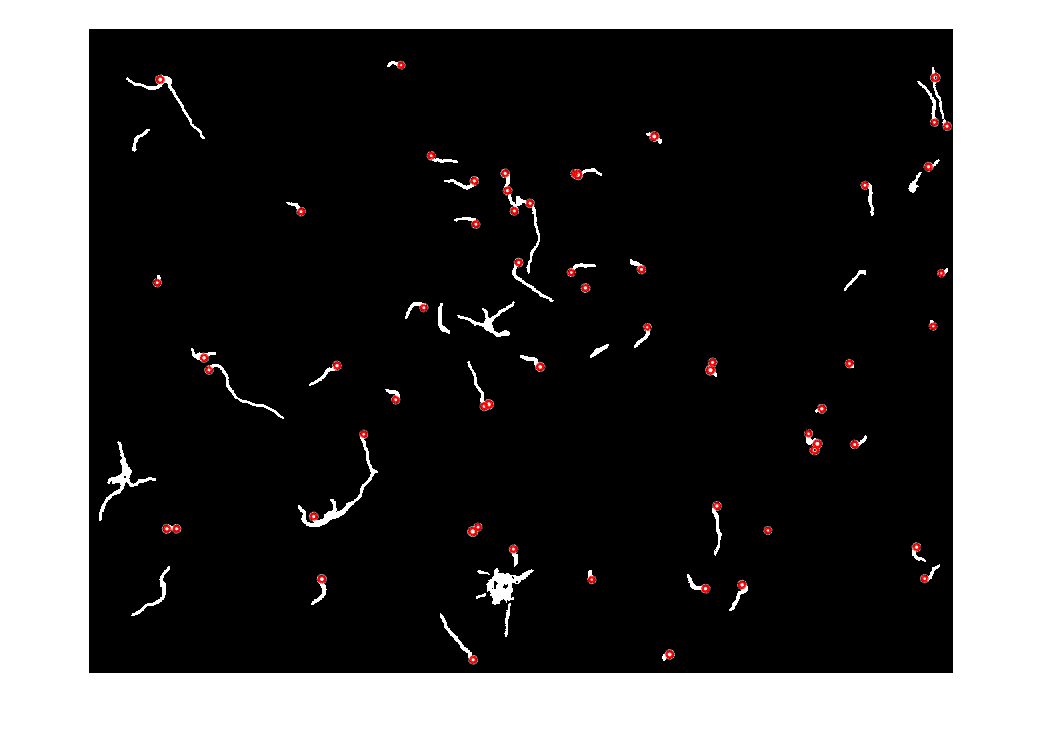

viscircles(Centers,Radii);

% ConnComp=bwconncomp(Bin,4);
% N=ConnComp.NumObjects;
% stat=regionprops(ConnComp,'all');    
%          for j=1:N        
%             x=stat(j).PixelList(:,1);
%             y=stat(j).PixelList(:,2);                   %for each detected connected component
%             if stat(j).Area<=620
%                 Bin(y,x)=0;
%             end   
%             
%             X=find(or(x<=10, x>=(size(Bin,2)-10)));
%             Y=find(or(y<=10, y>=(size(Bin,1)-10)));
% 
% %             if numel(X)>=1
% %                 Bin(y,x)=0;
% %             end
% %             if numel(Y)>=1
% %                 Bin(y,x)=0;
% %             end
%          end
            

% figure;
% imshow(Bin);
% [Centers,Radii]=imfindcircles(Bin,[6 25],'Sensitivity',0.9 ...
%     ,'EdgeThreshold',0.89,'ObjectPolarity','dark');
% viscircles(Centers,Radii);

%METHOD2=background leftovers (Image 11) & not well defined edges (Image 9)
%May be used for images with very few (1 or 2) germinative tubes
I=readimage(Images,3);
I=rgb2gray(I);
I=imadjust(I);
% figure;
% imshow(I);
I=mat2gray(I);
filteredImage = stdfilt(I, ones(13));
filteredImage=imcomplement(filteredImage);
%filteredImage=imadjust(filteredImage);
filteredImage=imbinarize(filteredImage,'adaptive','Sensitivity',0.78); 
filteredImage=imcomplement(filteredImage);
ConnComp=bwconncomp(filteredImage,4);
N=ConnComp.NumObjects

N = 53

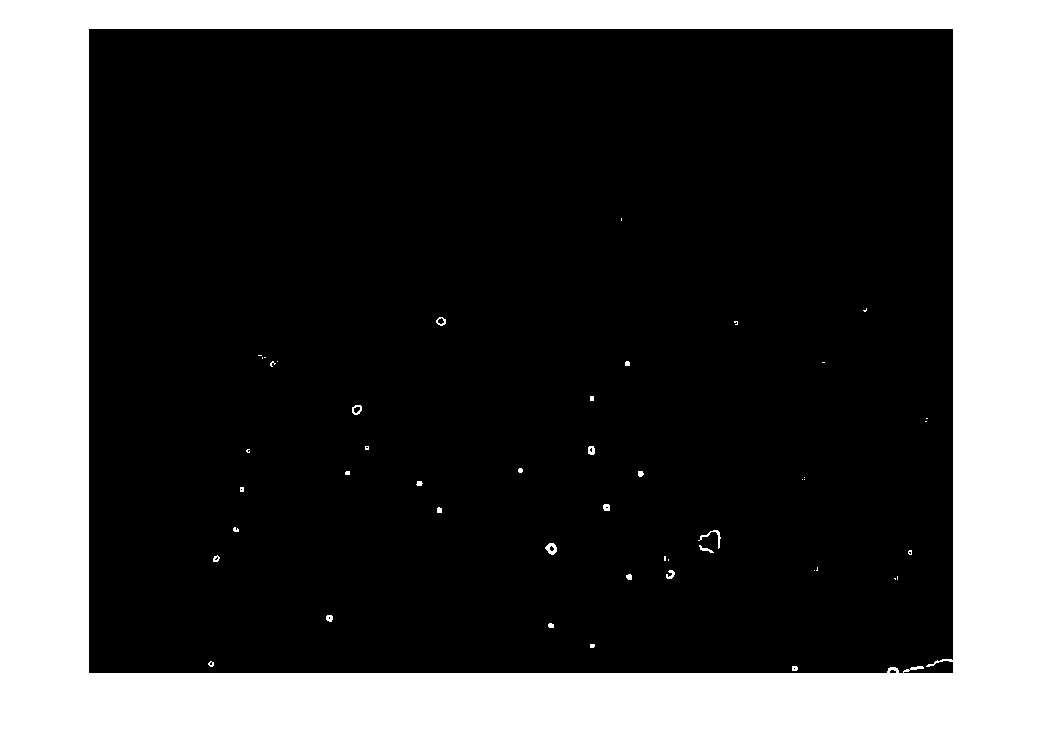

stat=regionprops(ConnComp,'all');
figure;
imshow(filteredImage);

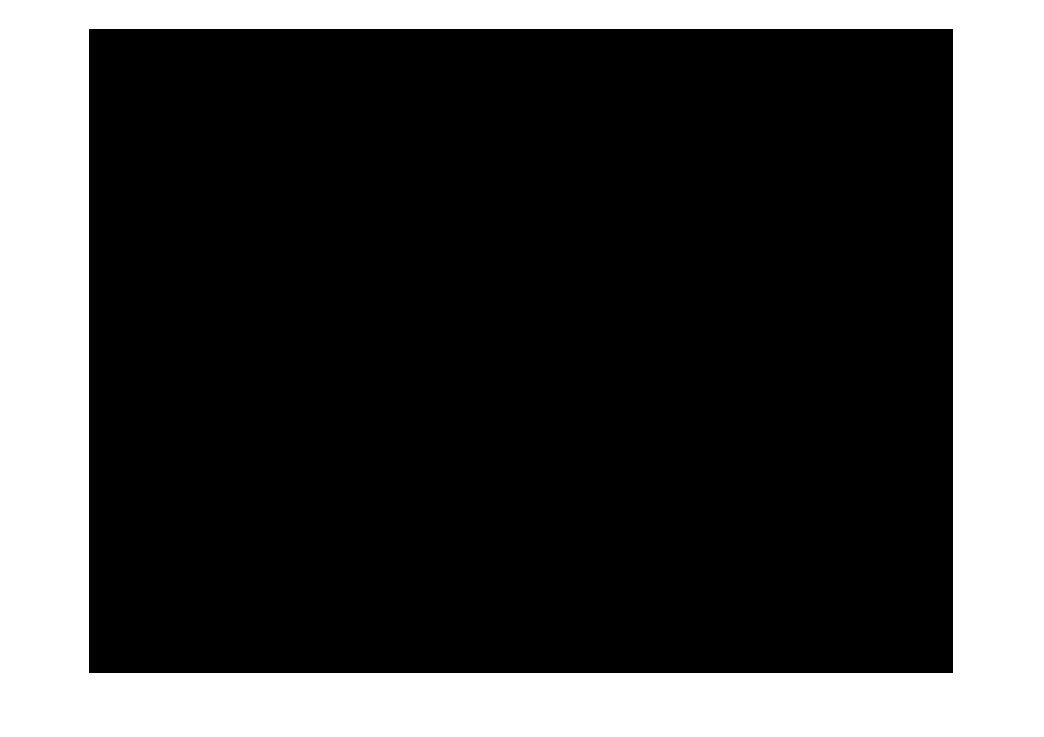

for j=1:N
       x=stat(j).PixelList(:,1);
       y=stat(j).PixelList(:,2);
            
       if stat(j).Area<=1500            %find the isolated (non germinated) spores
           filteredImage(y,x)=0;                    %delete them from binary image--> only germinated spores left
       else
           stat(j).Area
       end  
end
figure;
imshow(filteredImage);

% figure;
% imshow(I);
[Centers,Radii]=imfindcircles(filteredImage,[9 18],'Sensitivity',0.93 ...
   ,'EdgeThreshold',0.89,'ObjectPolarity','bright');
viscircles(Centers,Radii);

%METHOD3=salt&pepper for images with no germinated spores
I=readimage(Images, 6);
%I=imadjust(I);
% figure;
% imshow(I);
labI=rgb2lab(I);
ab=labI(:,:,1:2);
ab=im2single(ab);
nColors=2;
pixel_labels=imsegkmeans(ab,nColors,'NumAttempts',3);
Bin=imbinarize(pixel_labels);
ConnComp=bwconncomp(Bin,4);
ConnComp.NumObjects

ans = 2372

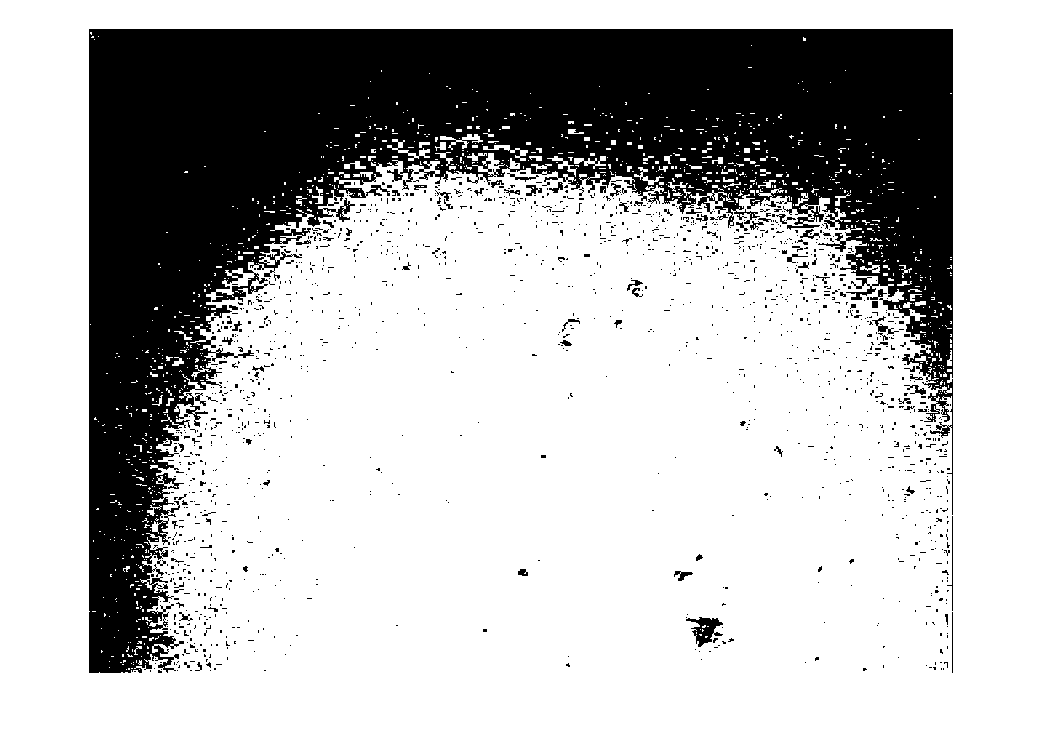

color=10;
increment=(256-color)/ConnComp.NumObjects;
for i=1:ConnComp.NumObjects
     PixId=ConnComp.PixelIdxList{i};
     I(PixId)=color;
     color=color+increment;
end
figure;
imshow(Bin,[]);

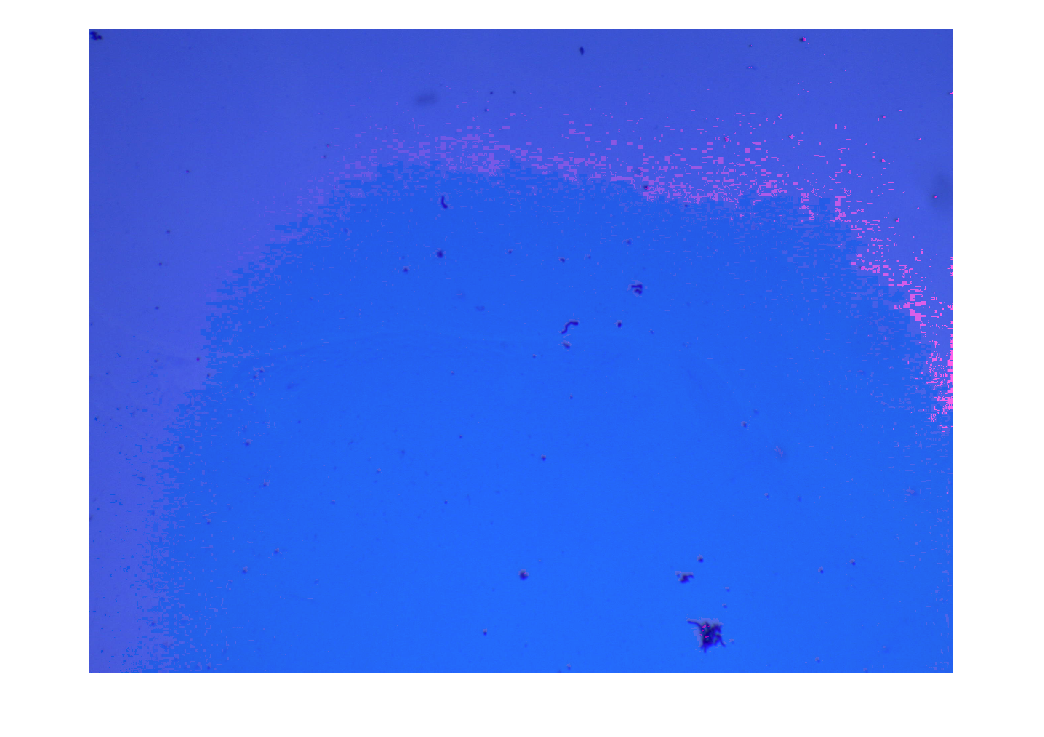

figure;
imshow(I);

%%%%%%%%%%%%%%%%%%% 
%Spore detection with Method 3
% varType={'string','single','single'};
% varName={'FileName','numDetectedSporesAsCircles','ConnComp'};
% CountedSpores3=table('Size',[numel(Images.Files) 3],'VariableTypes',varType,'VariableName',varName);
for i=1:numel(Images.Files)
    [I,info]=readimage(Images,i);
    labI=rgb2lab(I);
    ab=labI(:,:,1:2);
    ab=im2single(ab);
    nColors=2;
    pixel_labels=imsegkmeans(ab,nColors,'NumAttempts',3);
    Bin=imbinarize(pixel_labels);   
    
    ConnComp=bwconncomp(Bin,4);
    N=ConnComp.NumObjects
    AreaTot=0;
    Singletons=[];
    AreaSpores=0;
    if N<150                                %check if there are germinative tube
         stat=regionprops(ConnComp,'all');    
         for j=1:N                          %for each detected connected component
            if stat(j).Area<=620            %find the isolated (non germinated) spores
                Singletons(end+1)=j;        %add the detected non germinated spores to list of Singletons
                x=stat(j).PixelList(:,1);   %identify coordinates of singletons
                y=stat(j).PixelList(:,2);
                Bin(y,x)=0;                 %delete them from binary image--> only germinated spores left
            end            
         end
    
        figure;
        imshow(I);
        [Centers,Radii]=imfindcircles(Bin,[11 20],'Sensitivity',0.9);     %look for circles(spores) in binary image in which non germinated spores have been removed  
        [columns rows]=meshgrid(1:size(Bin,2),1:size(Bin,1));
        SporesCenters=[];               
        SporesRadii=[];
        for k=1:numel(Radii)
            x=floor(Centers(k,1));          
            y=floor(Centers(k,2));
            array2D = (rows- y).^2+ (columns - x).^2<(Radii(k)-5)^2;
            if Bin(array2D)==1              %if the circle contains only white pixels it means that it is really a spore
                viscircles([x y],Radii(k));
                SporesCenters=[SporesCenters;[x y]]; %save location of detected spore
                SporesRadii(end+1)=Radii(k);        
                sporearea=(rows- y).^2+ (columns - x).^2<(Radii(k))^2;
                %Bin(sporearea)=0;
                AreaSpores=AreaSpores+numel(sporearea);
            end
        end 
        [Centers1,Radii1]=imfindcircles(Bin,[11 25],'Sensitivity',0.9);
        for k=1:numel(Radii1)
            xx=floor(Centers1(k,1));
            yy=floor(Centers1(k,2)); 
            array2D = (rows- yy).^2+ (columns - xx).^2<(Radii1(k)-5)^2;
            if numel(find(SporesCenters==[xx yy]))==0 & Bin(array2D)==1
                viscircles([xx yy],Radii1(k));
                SporesCenters=[SporesCenters;[xx yy]];
                SporesRadii(end+1)=Radii1(k);  
                sporearea=(rows- yy).^2+ (columns - xx).^2<(Radii1(k))^2;
                %Bin(sporearea)=0;
                AreaSpores=AreaSpores+numel(sporearea);
            end
            
        end        
        NumGerminatedSpores=numel(SporesRadii) %how many germinated spores have been detected
        %different way to extract binary image: works better to remove edge-touching spores
        I=rgb2gray(I);
        I=mat2gray(I);
        filteredImage = stdfilt(I, ones(25));
        filteredImage=imcomplement(filteredImage);
        filteredImage=imbinarize(filteredImage,'adaptive','Sensitivity',0.7); 
        Bin_1=imcomplement(filteredImage);
        
        ConnComp_1=bwconncomp(Bin_1,4);
        N_1=ConnComp_1.NumObjects;
        stat_1=regionprops(ConnComp_1,'all');    
        for j=1:N_1       
            x=stat_1(j).PixelList(:,1);
            y=stat_1(j).PixelList(:,2);                   %for each detected connected component
                    
            X=find(or(x<=5, x>=(size(Bin_1,2)-5)));
            Y=find(or(y<=5, y>=(size(Bin_1,1)-5)));

            if numel(X)>=1
                Bin(y,x)=0;
            end
            if numel(Y)>=1
                Bin(y,x)=0;
            end
         end
         figure;
         imshow(Bin);
    end
end


%Spore detection with Method 2=too many circles (multiples for germinated
%spores, both end sides detected as circles)
varType={'string','single'};
varName={'FileName','numDetectedSporesAsCircles'};%,'AreaSpores'
CountedSpores2=table('Size',[numel(Images.Files) 2],'VariableTypes',varType,'VariableName',varName);
for i=1:numel(Images.Files)
    [I,info]=readimage(Images,i);
    I=rgb2gray(I);
    I=mat2gray(I);
    %I=imresize(I,[1000 1000]);
%     figure;
%     imshow(I);
    filteredImage = stdfilt(I, ones(3));
%     figure;
%     imshow(filteredImage,[]);
    filteredImage=imcomplement(filteredImage);
    filteredImage=imbinarize(filteredImage,'adaptive','Sensitivity',0.7); 
    figure;
    imshow(filteredImage, []); 
    %Comp=bwconncomp(filteredImage);
    [Centers,Radii]=imfindcircles(filteredImage,[5 17],'Sensitivity',0.91 ...
    ,'EdgeThreshold',0.7,'ObjectPolarity','dark');
    viscircles(Centers,Radii);   
    nSpores=numel(Radii); 
    CountedSpores2(i,:)={sprintf('%s',info.Filename(23:end-4)),nSpores};  
%     newname=sprintf('%s_only_spores.tif',info.Filename(23:end-4));
%     fullFileName=fullfile('D:\Spores\Images\X100',newname);
%     imwrite(filteredImage,fullFileName);
end
CountedSpores2


[CountPixels,PixelValue]=imhist(I);
CountDarkPixels=sum(CountPixels(1:121))
